clear variables;

demo = false;

## Create Numerical Loops

fex = 100;  % excitation frequency (Hz)
N_cycles = 2;
cycle_points = 600;
m = 3000;
noise = 'fft';
random_value_generator = 'uniform';
training_cycles = N_cycles;

cd ..\create_numerical_loops
numerical_loops = create_loops(fex, N_cycles, cycle_points, m, noise, ...
    random_value_generator, training_cycles);


cd ..\experimental_data
load real_loops.mat;
cd ..\model_1

## Classification using the existing model

pct_train = 0;  % no need to train a new model
[~, loops_test, ~, ~, Xtest, ytest] = choose_features(numerical_loops, ...
                                            'slip', pct_train);

load mdl_classification.mat;
y_pred = predict(mdl_classification, Xtest);
fprintf('Percentage of loops correctly classified: %0.2f%%\n', ...
            mean(y_pred == ytest)*100);

Percentage of loops correctly classified: 99.83%



loops_slip = loops_test(y_pred == 1,:);  % extract loops with gross slip
fprintf('Number of slip: %d | Number of stick: %d\n\n', ...
                            size(loops_slip, 1), m - size(loops_slip, 1));

Number of slip: 2687 | Number of stick: 313



## Visualise numerical loops

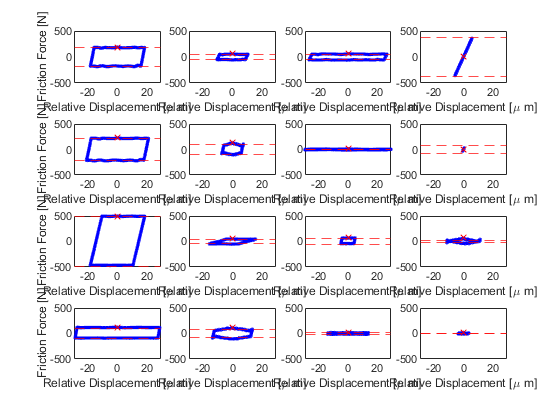

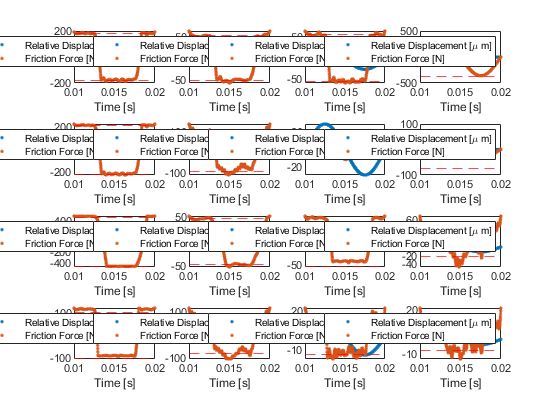

cd ..
normalise = false;
idx = randperm(m, 16);
plot_loops_individual(numerical_loops(idx,:), normalise);

cd model_1

## Choose features for training and testing

pct_train = 0.8;
[~, loops_test, Xtrain, ytrain, Xtest, ytest] = choose_features(loops_slip, ...
                                            'kt_slip', pct_train);

## Train the model

|====================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |      Epsilon |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |      7.9995 |      3.4564 |      7.9995 |      7.9995 |       147.85 |     0.016501 |       1742.9 |
|    2 | Accept |      7.9997 |      1.7186 |      7.9995 |      7.9995 |    0.0043507 |    0.0021163 |       81.515 |
|    3 | Best   |      7.9976 |      7.4674 |      7.9976 |      7.9976 |     0.011046 |       135.61 |     0.071829 |
|    4 | Accept |      7.9995 |     0.47117 |      7.9976 |      7.9976 |    0.0012275 |        84.61 |         4531 |
|    5 | Best   |      7.9465 |      7.4921 |   

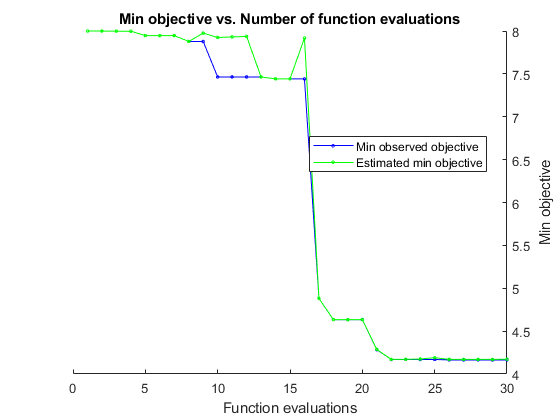


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 286.4934 seconds
Total objective function evaluation time: 250.923

Best observed feasible point:
    BoxConstraint    KernelScale    Epsilon 
    _____________    ___________    ________

       991.17          41.699       0.096932

Observed objective function value = 4.164
Estimated objective function value = 4.1712
Function evaluation time = 19.8626

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale    Epsilon
    _____________    ___________    _______

       996.77          45.643       0.38949

Estimated objective function value = 4.173
Estimated function evaluation time 

mdl_kt_slip =   RegressionSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                    ResponseTransform: 'none'
                                Alpha: [1654×1 double]
                                 Bias: 159.5056
                     KernelParameters: [1×1 struct]
                                   Mu: [1×1200 double]
                                Sigma: [1×1200 double]
                      NumObservations: 2150
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                       BoxConstraints: [2150×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2150×1 logical]
                               Solver: 'SMO'


  Properties, Methods


if ~demo
rng('default');
% mdl_kt_slip = fitrsvm(Xtrain, ytrain,...
%             'Standardize', false, ...
%             'OptimizeHyperparameters',{'KernelFunction', 'KernelScale', 'BoxConstraint', 'Epsilon'},...
%             'HyperparameterOptimizationOptions',...
%             struct('AcquisitionFunctionName','expected-improvement-plus'))
mdl_kt_slip = fitrsvm(Xtrain, ytrain,...
            'RemoveDuplicates', false, ...
            'Standardize', true, ...
            'KernelFunction', 'gaussian', ...
            'OptimizeHyperparameters', {'KernelScale', 'BoxConstraint', 'Epsilon'},...
            'HyperparameterOptimizationOptions',...
            struct('AcquisitionFunctionName','expected-improvement-plus'))
end

## Evaluate model performance

if demo
    load mdl_kt_slip.mat
end

fprintf('\n========== slip numerical loops ==========\n');


========== slip numerical loops ==========


fprintf('Training error: %0.2f%%\n', ...
            mean(abs((predict(mdl_kt_slip, Xtrain)-ytrain)./ytrain))*100);

Training error: 1.43%


Convergent with 50885 iterations.
mean error: 4.39%, highest error: 349.47% at 306
total elapsed time: 286


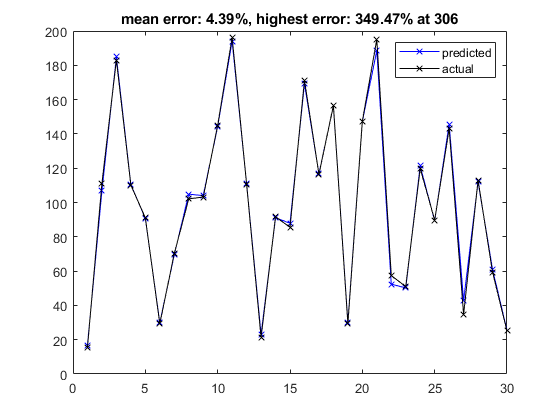

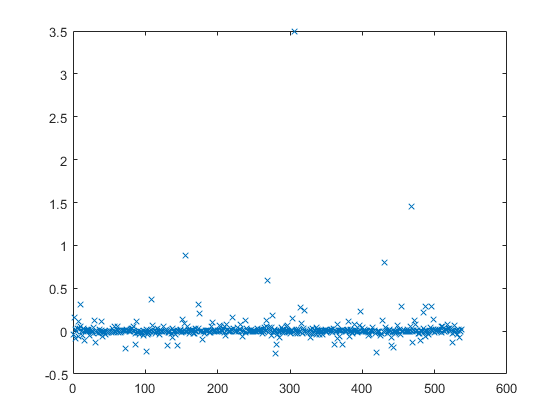

[y_pred, error] = evaluate_mdl_reg(mdl_kt_slip, Xtest, ytest, demo);